ЛАБОРАТОРНА РОБОТА №4

з навчальної дисципліни «Математичне моделювання систем і процесів»

Виконав:

Студент 5 курсу

Групи ФФ-21мн

Бондар О.В.

Перевірив:

Гордійко Н.О.

Варіант №1 

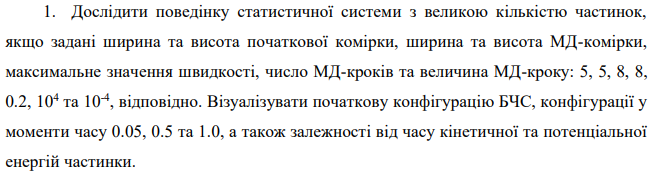

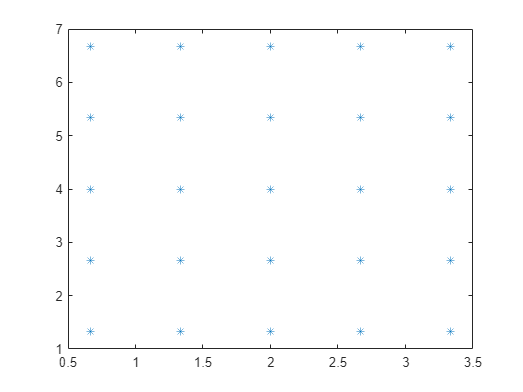

clearvars;
Nx=5;
Ny=5;
Lx=8;
Ly=8;

Vmax=0.2;
dt=10^(-4);
Ni=10^4;


N=Nx*Ny;

Posrow=Ly/(Ny+1); Poscol=Lx/(Nx+1);
i=1;
for Rows=1:Ny
    for Col=1:Nx
        x(i)=Poscol*Col/2; 
        y(i)=Posrow*Rows; 
        Vx(i)=Vmax*(2*rand(1)-1); 
        Vy(i)=Vmax*(2*rand(1)-1);
        i=i+1;
    end
end
plot(x,y, '*')


T=0;
T1=0.05;
T2=0.5;
T3=1.0;


RV=init(Lx,Ly,Nx,Ny,Vmax,T) 

RV =     0.6667    1.3333   -0.0837    0.1041
    1.3333    1.3333    0.0622    0.0393
    2.0000    1.3333    0.0749    0.0903
    2.6667    1.3333   -0.1331   -0.1251
    3.3333    1.3333    0.1953   -0.1079
    0.6667    2.6667   -0.1913    0.0481
    1.3333    2.6667    0.1484    0.0913
    2.0000    2.6667   -0.1281   -0.0288
    2.6667    2.6667   -0.0200    0.2163
    3.3333    2.6667   -0.1418    0.1659


accfunc=Acc(RV,Lx,Ly,N)

accfunc = 1.0e+03 *

   -6.1681    0.0023         0
    0.0017    0.0031         0
   -0.0000    0.0032         0
   -0.0017    0.0031         0
    6.1681    0.0023         0
   -6.1676    0.0000         0
    0.0019    0.0001         0
   -0.0000    0.0001         0
   -0.0019    0.0001         0
    6.1676    0.0000         0



z1=Fx(x,y)

z1 =    -0.3706   -0.1322   -0.0294   -0.0071   -0.0020   -0.0034   -0.0035   -0.0022   -0.0011   -0.0005   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


z2=Fy(x,y)

z2 =    -0.7413   -0.1322   -0.0196   -0.0035   -0.0008   -0.0135   -0.0071   -0.0029   -0.0011   -0.0004   -0.0009   -0.0007   -0.0004   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


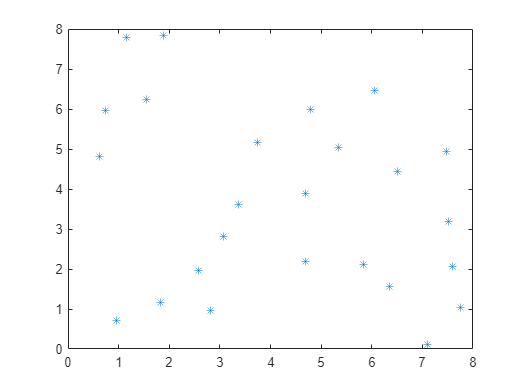

md = md(:,:,1) =

   1.0e+03 *

    0.0007    0.0013   -0.0001    0.0001   -6.1681    0.0023         0
    0.0013    0.0013    0.0001    0.0000    0.0017    0.0031         0
    0.0020    0.0013    0.0001    0.0001   -0.0000    0.0032         0
    0.0027    0.0013   -0.0001   -0.0001   -0.0017    0.0031         0
    0.0033    0.0013    0.0002   -0.0001    6.1681    0.0023         0
    0.0007    0.0027   -0.0002    0.0000   -6.1676    0.0000         0
    0.0013    0.0027    0.0001    0.0001    0.0019    0.0001         0
    0.0020    0.0027   -0.0001   -0.0000   -0.0000    0.0001         0
    0.0027    0.0027   -0.0000    0.0002   -0.0019    0.0001         0
    0.0033    0.0027   -0.0001    0.0002    6.1676    0.0000         0
    0.0007    0.0040    0.0001   -0.0000   -6.1676    0.0000         0
    0.0013    0.0040   -0.0001   -0.0000    0.0019    0.0000         0
    0.0020    0.0040   -0.0000   -0.0001   -0.0000    0.0000         0
    0.0027    0.0040    0.0000   -0.0001   -0


% verletfunc=Verlet(RV,Lx,Ly,N,dt)

md=MD(Lx,Ly,N,Ni,dt,RV)




RV1=init(Lx,Ly,Nx,Ny,Vmax,T1) 

RV1 =     0.6651    1.3252   -0.0159   -0.1692
    1.3353    1.3328    0.0544   -0.0185
    2.0039    1.3373    0.0933    0.0731
    2.6694    1.3240    0.0704   -0.1934
    3.3247    1.3297   -0.1575   -0.0790
    0.6673    2.6698    0.0273    0.0549
    1.3315    2.6731   -0.0220    0.1211
    2.0044    2.6760    0.1023    0.1806
    2.6673    2.6632    0.0275   -0.0768
    3.3254    2.6689   -0.1428    0.0375


accfunc1=Acc(RV1,Lx,Ly,N)

accfunc1 = 1.0e+03 *

   -5.7470   -0.0624         0
   -0.1829    0.0270         0
   -0.3612    0.1698         0
   -1.4576   -0.1907         0
    7.7487    0.0700         0
   -6.4774   -0.0321         0
    1.0280    0.0084         0
   -1.1768    0.1531         0
   -0.6845   -0.1923         0
    7.3106    0.0636         0


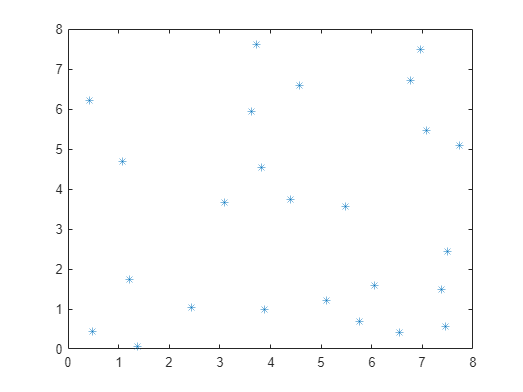

md1 = md1(:,:,1) =

   1.0e+03 *

    0.0007    0.0013   -0.0000   -0.0002   -5.7470   -0.0624         0
    0.0013    0.0013    0.0001   -0.0000   -0.1829    0.0270         0
    0.0020    0.0013    0.0001    0.0001   -0.3612    0.1698         0
    0.0027    0.0013    0.0001   -0.0002   -1.4576   -0.1907         0
    0.0033    0.0013   -0.0002   -0.0001    7.7487    0.0700         0
    0.0007    0.0027    0.0000    0.0001   -6.4774   -0.0321         0
    0.0013    0.0027   -0.0000    0.0001    1.0280    0.0084         0
    0.0020    0.0027    0.0001    0.0002   -1.1768    0.1531         0
    0.0027    0.0027    0.0000   -0.0001   -0.6845   -0.1923         0
    0.0033    0.0027   -0.0001    0.0000    7.3106    0.0636         0
    0.0007    0.0040    0.0001   -0.0000   -8.1315    0.0390         0
    0.0013    0.0040   -0.0001   -0.0001    2.1182   -0.0419         0
    0.0020    0.0040   -0.0001   -0.0001    0.5125   -0.0378         0
    0.0027    0.0040   -0.0000    0.0000   

md1=MD(Lx,Ly,N,Ni,dt,RV1)


RV2=init(Lx,Ly,Nx,Ny,Vmax,T1) 

RV2 =     0.6750    1.3234    0.1897   -0.2196
    1.3326    1.3318    0.0083   -0.0503
    1.9992    1.3387    0.0077    0.0880
    2.6631    1.3390   -0.0477    0.0939
    3.3328    1.3240    0.0119   -0.2057
    0.6602    2.6711   -0.1063    0.0687
    1.3328    2.6597    0.0127   -0.1589
    1.9968    2.6688   -0.0402    0.0229
    2.6605    2.6714   -0.1000    0.0753
    3.3282    2.6750   -0.0795    0.1469


accfunc2=Acc(RV2,Lx,Ly,N)

accfunc2 = 1.0e+03 *

   -7.3889   -0.0928         0
    1.2235    0.0342         0
   -0.3514    0.0643         0
    0.7240    0.1356         0
    5.7928   -0.1274         0
   -5.4692    0.0927         0
   -1.0223   -0.1816         0
   -0.0524    0.0632         0
    0.5018   -0.0065         0
    6.0421    0.0326         0


md2=MD(Lx,Ly,N,Ni,dt,RV2)

RV3=init(Lx,Ly,Nx,Ny,Vmax,T1) 
accfunc3=Acc(RV3,Lx,Ly,N)
md3=MD(Lx,Ly,N,Ni,dt,RV3)




% розрахунок енергій
Ep=0;
for i=1:N-1
    for j=i+1:N
        Dx=x(i)-x(j);
        if abs(Dx)>Lx/2
            Dx=Dx-sign(Dx)*Lx;
        end
        Dy=y(i)-y(j);
        if abs(Dy)>Ly/2
            Dy=Dy-sign(Dy)*Ly;
        end
        r=(Dx^2+Dy^2).^0.5; 
        Ep=Ep+4*(1/r.^12-1/r.^6);
    end
end
Ek=0;
for i=1:N
    Ek=Ek+0.5*(Vx(i)^2+Vy(i)^2);
end
Ep
Ek
Esum = Ep+Ek 

